# LU decomposition 

***(In this method we didnot performed partial pivoting. So, matrix containing to many 0 entry will not produce accurate result.But this process is very simple to use as it has algorithomic complexity of (***$n^2$***).***

In numerical analysis and linear algebra, LU decomposition (where ‘LU’ stands for ‘lower upper’, and also called LU factorization) factors a matrix as the product of a lower triangular matrix and an upper triangular matrix. Computers usually solve square systems of linear equations using the LU decomposition, and it is also a key step when inverting a matrix, or computing the determinant of a matrix.LU decomposition can be performed  in many ways an one of the simple ways to solve it by using doolittle algorithm.

## ***Doolittle Algorithm ****:* 

It is always possible to factor a square matrix into a lower triangular matrix and an upper triangular matrix. That is, **[A] = [L][U]. **For a general n×n matrix A, we assume that an LU decomposition exists, and write the form of L and U explicitly. We then systematically solve for the entries in L and U from the equations that result from the multiplications necessary for** A=LU**.

###             **Upper Triangular Matrix:** 

                                                                 The element of upper triangular matrix can be viewed as follows 

 U= $\left\lbrack \begin{array}{cccc}
U_{11}  & U_{12}  & U_{13}  & U_{14} \\
0 & U_{22}  & U_{23}  & U_{24} \\
0 & 0 & U_{33}  & U_{34} \\
0 & 0 & 0 & U_{44} 
\end{array}\right\rbrack$

                                                    1. 1st row in Upper triangular matrix is same as the 1st row of matrix A

                                                    2. Rest of the element are zero except 

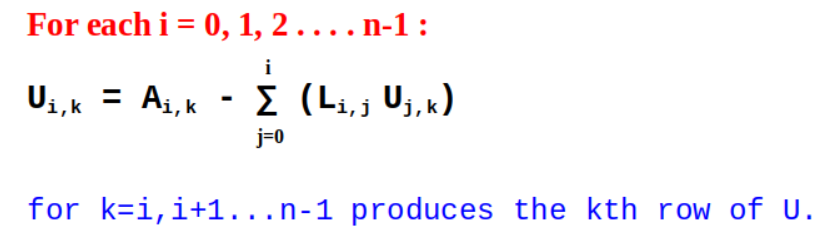

###         **Lower Triangular Matrix:**

                                                            The element of lower triangular matrix can be viewed  as 

L=$\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
l_{21}  & 1 & 0 & 0\\
l_{31}  & l_{32}  & 1 & 0\\
l_{41}  & l_{42}  & l_{43}  & 1
\end{array}\right\rbrack$

                                        1. All the diagonal element will be 1.

                                         2. Rest of the element will be zero except 

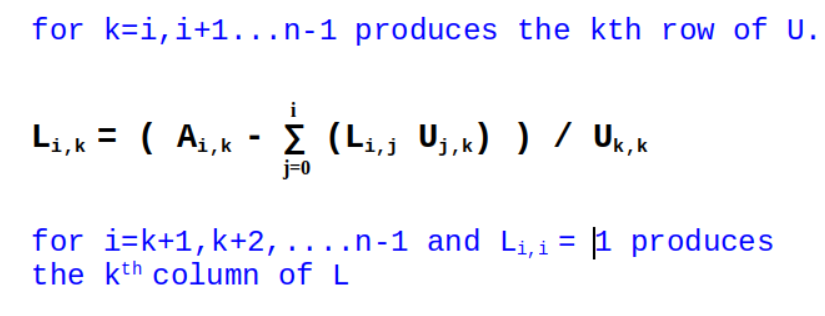

After finding  **L** and **U** matrix we will perform forward elimination and backword substitution.

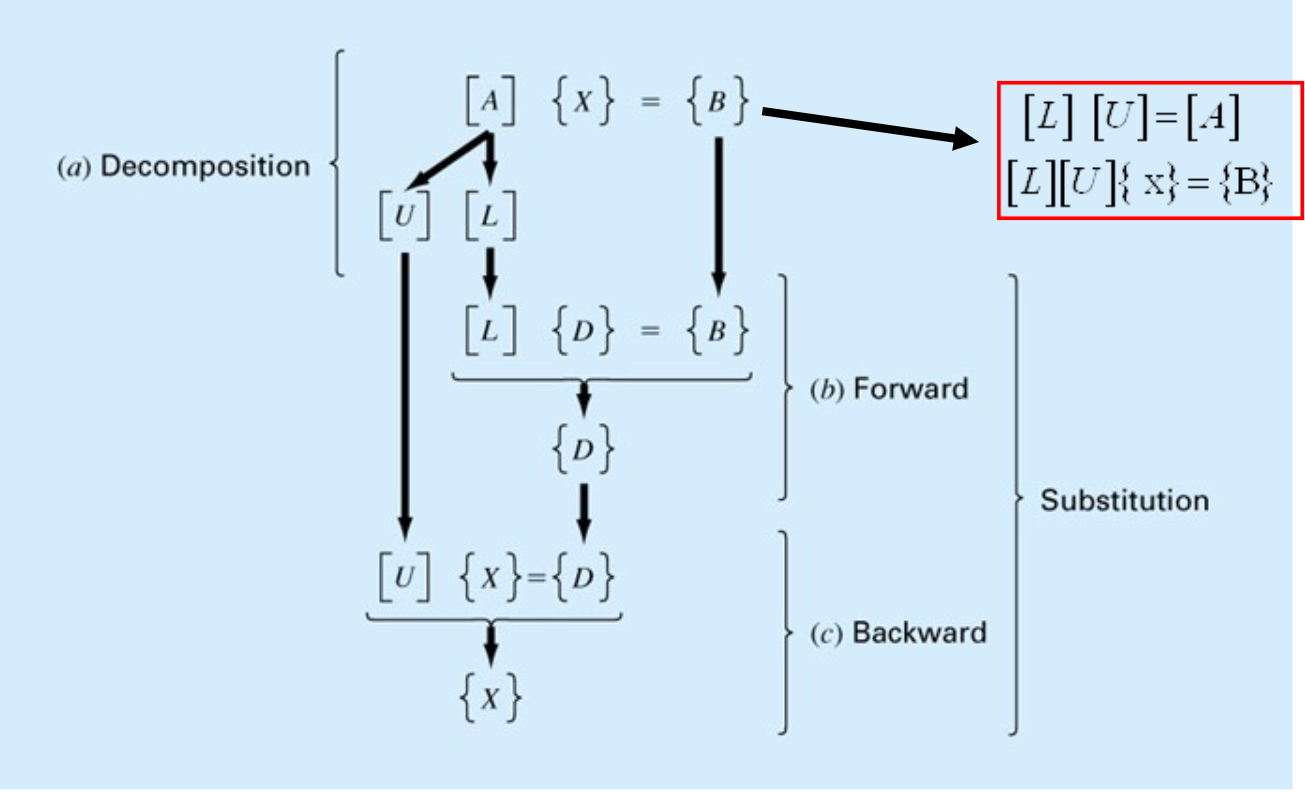

### **Step 1 :Input of Matrix and Vector **

We will store the matrix in **A** and vector in **b**. (*One important thing is here b is a vector and it has only one column .So while inputing the b vector carefully ; has to be written after given each entry)*

A = input("Enter your Co-efficient matrix:");
b = input ("Enter your b vector (column vector):");


### **Step 2 : Creating L and U matrix with all Zeros entry** 

As we want to create two different matrix **L** and **U** ,so  we need to know the order of matrix **A**. ***length*** function can be used to know the order of square matrix A.

Then we will create two separate matrix **L** and **U** of $n\ast n\;$ order where all the entries are **zero**.

n = length(A);               % Length of co-efficient matrix
L = zeros(n,n);              % L matrix all the entry zeros
U = zeros(n,n);              % U matrix all the entry zeros 

### **Step 3 : Replacing 0 with 1 to all the diagonal element in Lower Triangular matrix **

### L=$\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
l_{21}  & 1 & 0 & 0\\
l_{31}  & l_{32}  & 1 & 0\\
l_{41}  & l_{42}  & l_{43}  & 1
\end{array}\right\rbrack$ 

From the example of lower triangular matrix we can see that all the diagonal element are 1. So we will replace **0** in diagonal element with **1** in lower triangular matrix. 

for i=1 : n
    L(i,i) = 1;              % L matrix all the diogonal element 1
end

### **Step 4 : First row of Upper Triangular Matrix is same as the first row of given matrix A**

$\left\lbrack \begin{array}{cccc}
a_{11}  & a_{12}  & a_{13}  & a_{14} \\
a_{21}  & a_{22}  & a_{23}  & a_{24} \\
a_{31}  & a_{32}  & a_{33}  & a_{34} \\
a_{41}  & a_{42}  & a_{43}  & a_{44} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
l_{21}  & 1 & 0 & 0\\
l_{31}  & l_{32}  & 1 & 0\\
l_{41}  & l_{42}  & l_{43}  & 1
\end{array}\right\rbrack *\left\lbrack \begin{array}{cccc}
U_{11}  & U_{12}  & U_{13}  & U_{14} \\
0 & U_{22}  & U_{23}  & U_{24} \\
0 & 0 & U_{33}  & U_{34} \\
0 & 0 & 0 & U_{44} 
\end{array}\right\rbrack$-----------------------(i)

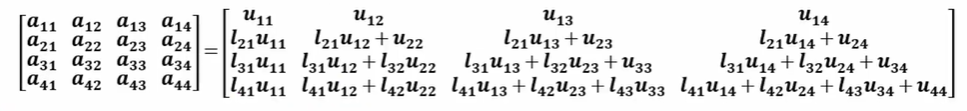

If we solve the above matrix multiplication equation we will find that the value of  $U_{11}$,$U_{12}$,$U_{13}$,$U_{14}$,$U_{15}$ will be same $a_{11}$,$a_{12}$,$a_{13}$,$a_{14}$,$a_{15}$. So the first First row of Upper Triangular Matrix is same as the first row of given matrix **A**.

%U matrix
U(1, :)= A(1,:);

### **Step 5 : First Coulm of Lower triangular Matrix is **$\frac{A_{\mathrm{Element}\;\mathrm{of}\;\mathrm{First}\;\mathrm{Row}\;} }{U_{11} }$

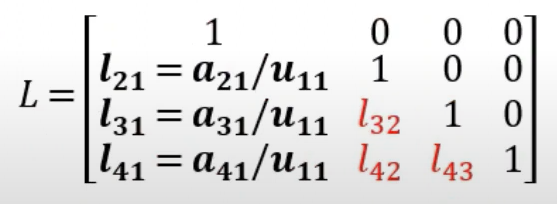

Solving the same equation we will get that the first colun of the lower triangular matrix will be $\frac{A_{\mathrm{Element}\;\mathrm{of}\;\mathrm{First}\;\mathrm{Row}\;} }{U_{11} }$.

% 1st Column of L
L(:,1) = A(:,1)/ U(1,1);

### **Step 6 : Rest of the element of U and L**

Solving the equation (i) we will get the rest of the non zero element of **L** and **U** matrix.The general form of the rest of the element is 

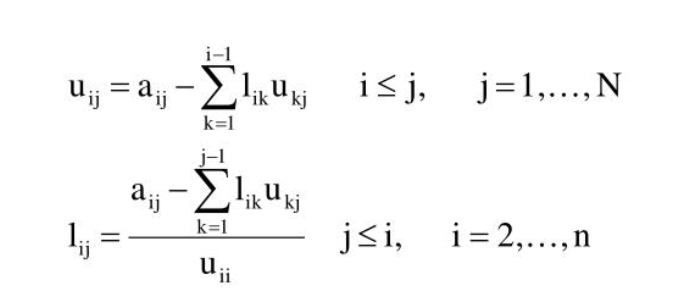

Our main for loop will start from 2 and end at **n** (length of matrix)

For the element of **U** matrix :

- Another For loop will iterate  from **i** to **n** and update the value of rest of the element of upper triangular matrix.Upon seenig the patttern from the $U_{22}$,$U_{23}$,$U_{24}$,$U_{33}$,$U_{34}$,$U_{44\;}$we will generalize a formula and present the element of U with iterator  *i,j*

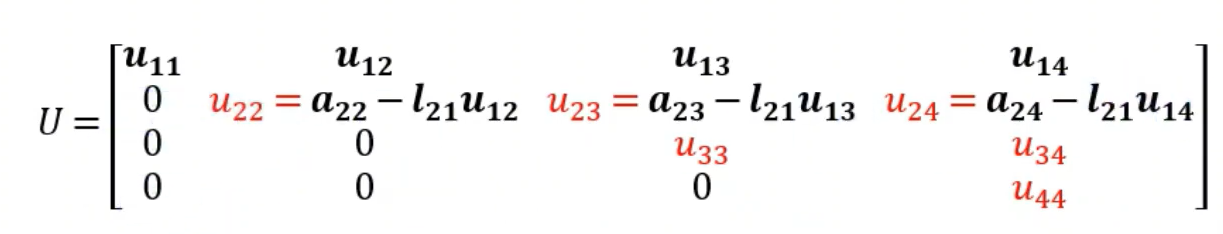

For the element of **U** matrix:

- Another For loop will iterate  from k=**i+1** to **n** and update the value of rest of the element of lower triangular matrix.From the pattern of the element of lower traingular matrix we can generalize a formula 

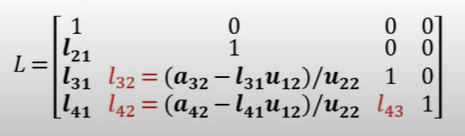

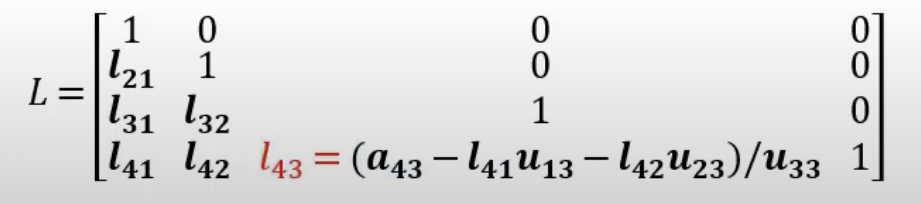

for i=2:n
    for j=i:n
        U(i,j)=A(i,j) - L(i,1:i-1)*U(1:i-1,j);      % element of U matrix 
    end
    for k= i+1 : n
        L(k,i)=(A(k,i)-L(k,1:i-1)*U(1:i-1,i))/U(i,i);   % element of L matrix 
    end
end


### Step 6 :Forward Substitution 

We have completed our L and  U matrix. Now we will start forward substitution

### **[A]{x}= b**

### **                             [L][U]{x}= b ---------------(ii)**

Let,  

### **                                                                              [U]{x} = D ------------------(iii)**

So our equation (ii) will be :

### **[L]{D}= b**

We can solve this equation by using ***ldivide*** in matlab.

D =L\b;

### Step 7 :Backward Elimination 

Our final step of the process is backward elimination. Form solving equation (ii) we will get a vector {D} , a column  vector that has n element. Now we will solve equation (iii) to get the value of x 

We can also use ***ldivide*** to get the final value of **{x}**

x=U\D